Rectangular function with respect to M=10


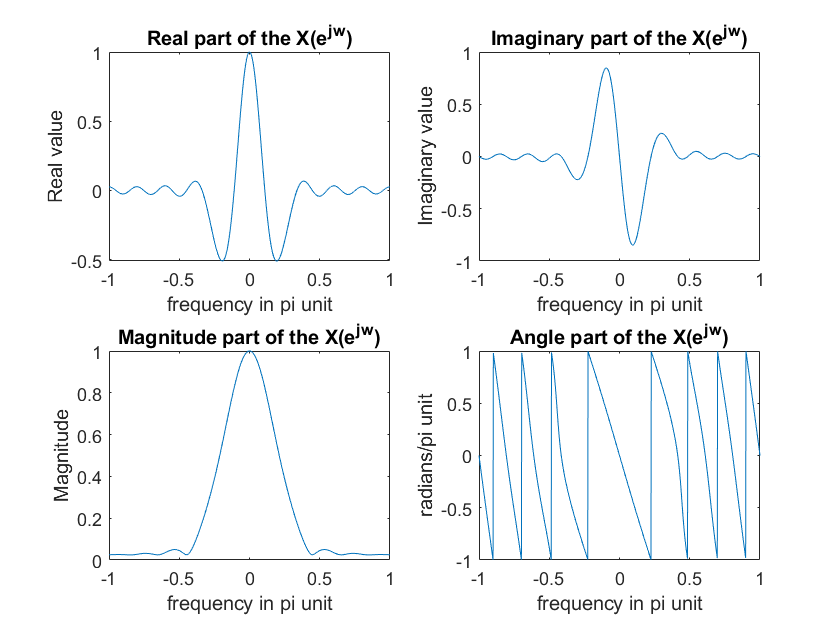

Rectangular function with respect to M=25


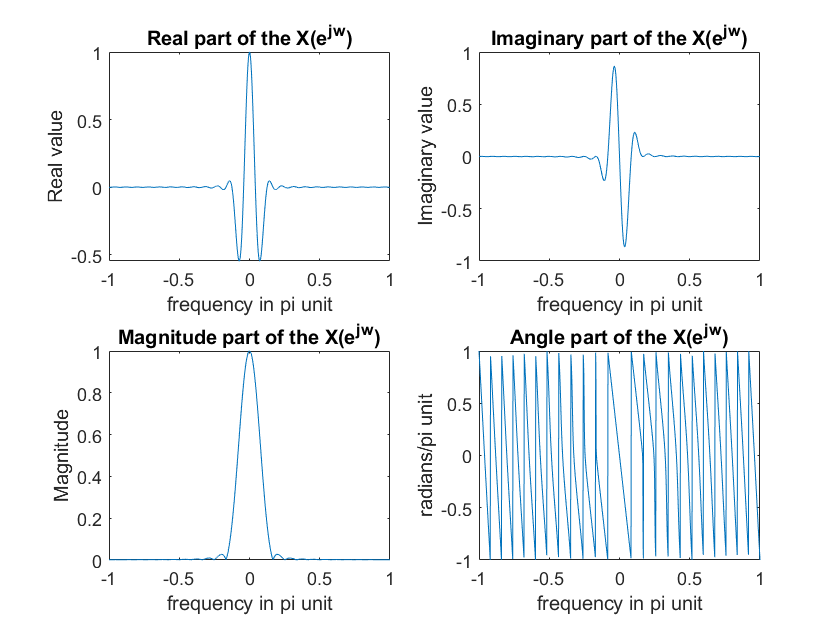

Rectangular function with respect to M=50


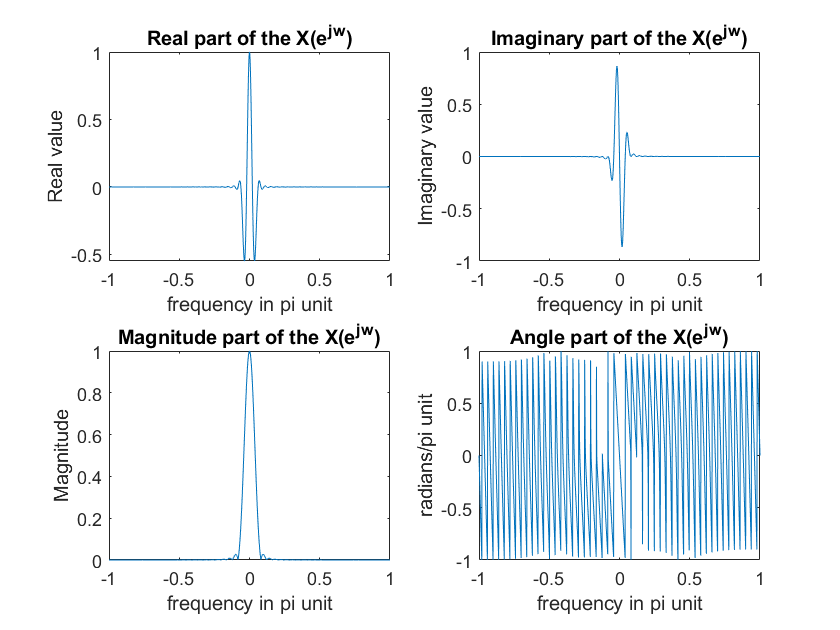

Rectangular function with respect to M=101


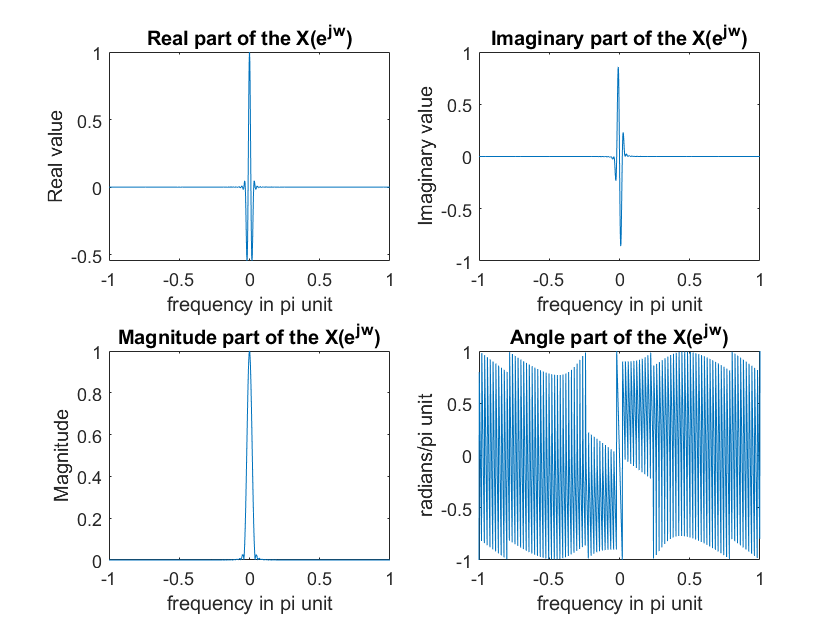

% Hanning Window
K=500;
k=-K:K;
w=(pi*k)/K;
M=[10 25 50 101];
for i=1:length(M)
    figure('Name',strcat('M=',num2str(M(i))))
    n=-50:M(i);
    han=0.5*unitseq(min(n),M(i),0).*(1-cos(2*pi*n./(M(i)-1)));
    X=dtft(han,n,w);
    disp(strcat('Hanning window function with respect to M=',num2str(M(i))))
    dfp4(X/max(X),w)
end